clear all
close all

%Matrix properties
A1 = [-1 -100;
    10 -1];
A2 = [1 10;
    -100 1];
E12 = [-8 -1];
E21 = [2 -1];
Q = 0.5 * [E12; E21].'*[0 1; 1 0] * [E12; E21];
R12 = eye(2); R21 = eye(2);


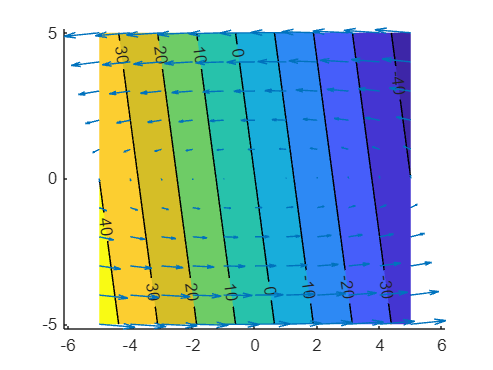


%plotting settings
min = -5;
max = 5;
stepsize = 1;

%plotting vector fields and edge countour plots individualy
figure() %mode 1
hold on
%edge field
[X,Y,p] = valuefield(E12,min,max,stepsize);
contourf(X,Y,p,'ShowText','on')

%vector field
[X,Y,u,v] = vectorfield(A1,min,max,stepsize);
quiver(X,Y,u,v)

hold off

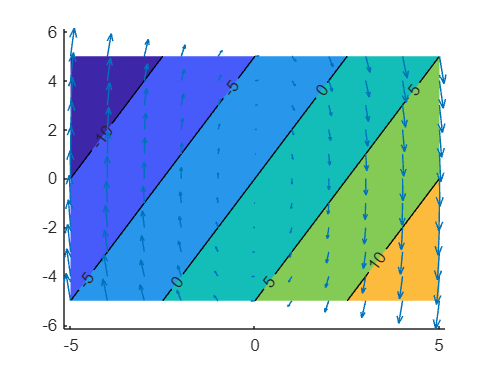



figure() %mode 2
hold on
[X,Y,p] = valuefield(E21,min,max,stepsize);
contourf(X,Y,p,'ShowText','on')

[X,Y,u,v] = vectorfield(A2,min,max,stepsize);
quiver(X,Y,u,v)

hold off

%plotting settings
vectorsize = 0.5

vectorsize = 0.5000

mapsize = 0.01

mapsize = 0.0100


min = -5

min = -5

max = 5

max = 5


%plotting vector field 1
figure()
clf; hold on

%plotting the invariant map
[X,Y,Qp] = Qfield(Q,min,max,mapsize);
contourf(X,Y,Qp,[0 0.01])

%computing and plotting the vectorfield
[X,Y,u,v] = vectorfield(A1,min,max,vectorsize); %computing vectorsfield
[X,Y,Qp] = Qfield(Q,min,max,vectorsize); %recomputing feasible area to create binary map
map = zeros(length(u)); map(Qp>=0) = 1;
quiver(X,Y,u.*map,v.*map) %plotting the mapped vectorfield

%computing edges
x = [min:vectorsize:max]

x =    -5.0000   -4.5000   -4.0000   -3.5000   -3.0000   -2.5000   -2.0000   -1.5000   -1.0000   -0.5000         0    0.5000    1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    4.0000    4.5000    5.0000


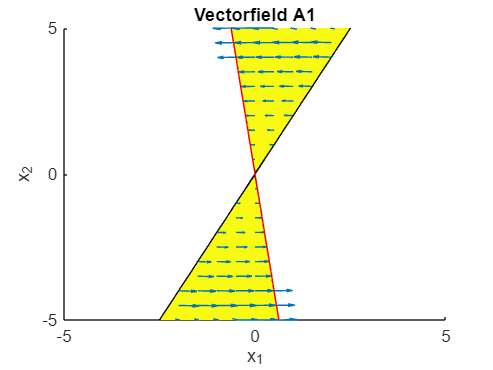

plot(x,-E12(1)/E12(2)*x','Color','r')
%plot(x,E21(1)/E21(2)*x,'Color','r')

ylim([min, max])
xlim([min, max])
title('Vectorfield A1')
xlabel('x_1'); ylabel('x_2')

hold off


figure()
clf; hold on
%plotting the invariant map
[X,Y,Qp] = Qfield(Q,min,max,mapsize);
contourf(X,Y,Qp,[0 0.01])

%computing and plotting the vectorfield
[X,Y,u,v] = vectorfield(A2,min,max,vectorsize); %computing vectorsfield
[X,Y,Qp] = Qfield(Q,min,max,vectorsize); %recomputing feasible area to create binary map
map = zeros(length(u)); map(Qp>=0) = 1;
quiver(X,Y,u.*map,v.*map) %plotting the mapped vectorfield

%computing edge
x = [min:vectorsize:max]

x =    -5.0000   -4.5000   -4.0000   -3.5000   -3.0000   -2.5000   -2.0000   -1.5000   -1.0000   -0.5000         0    0.5000    1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    4.0000    4.5000    5.0000


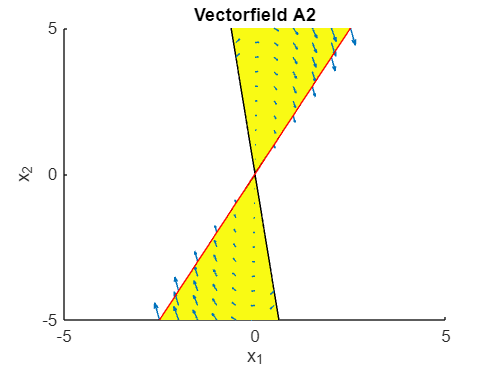

%plot(x,E12(1)/E12(2)*x','Color','r')
plot(x,-E21(1)/E21(2)*x,'Color','r')

ylim([min, max])
xlim([min, max])
title('Vectorfield A2')
xlabel('x_1'); ylabel('x_2')


hold off

eig(A1)

ans =   -1.0000 +31.6228i
  -1.0000 -31.6228i


eig(A2)

ans =    1.0000 +31.6228i
   1.0000 -31.6228i



A1*A2

ans =         9999        -110
         110          99


A2*A1

ans =           99        -110
         110        9999



A1_sys = @(x,t) A1*x;
A1_sys([1; 0],1)

ans =     -1
    10


A2_sys = @(x,t) A2*x;
[t,y] = ode45(A1_sys,[0 5],[1; 1])

Error using odearguments (line 94)
@(X,T)A1*X must return a column vector.

Error in ode45 (line 104)
    odearguments(odeIsFuncHandle,odeTreatAsMFile, solver_name, ode, tspan, y0, options, varargin);

syms x y 
X = [x; y]

$$X = \left(\begin{array}{c} x\\ y \end{array}\right)$$

X.'*Q*X

$$ans = y\,\left(3\,x+y\right)-x\,\left(16\,x-3\,y\right)$$

simplify(X.'*Q*X)

$$ans = -16\,x^{2}+6\,x\,y+y^{2}$$